clear;
X = load('data2.txt');
y = X(:,3);
X(:,3) = [];
% Create the polynomial feature matrix up to power 6
powers = [nchoosek(0:6,2); fliplr(nchoosek(0:6,2));1 1;2 2;3 3]';
powers(:,sum(powers)>6) = [];
Xpoly = (X(:,1).^powers(1,:)).*(X(:,2).^powers(2,:));


lambda = 0.00001;
logMdl = fitclinear(Xpoly,y,'Lambda',lambda,'Learner','logistic','Regularization','ridge')

logMdl =   ClassificationLinear
      ResponseName: 'Y'
        ClassNames: [0 1]
    ScoreTransform: 'logit'
              Beta: [27×1 double]
              Bias: 3.53647052402858
            Lambda: 1e-05
           Learner: 'logistic'


  Properties, Methods



% Obtain the class labels and compute the training accuracy
Pass = predict(logMdl,Xpoly);
fprintf('Train Accuracy: %f\n', mean(Pass == y) * 100);

Train Accuracy: 86.440678


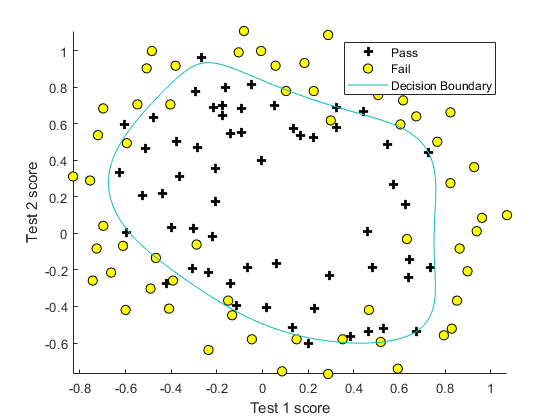


% Plot the positve and negative examples
figure; hold on;
plotMdlData(array2table([X y],'VariableNames',{'Test1','Test2','Pass'})); 

% Plot the decision boundary
xvals = linspace(min(X(:,1)), max(X(:,1)));
yvals = linspace(min(X(:,2)), max(X(:,2)));
[Xgrid, Ygrid] = meshgrid(xvals,yvals);
Xpolygrid = (Xgrid(:).^powers(1,:)).*(Ygrid(:).^powers(2,:));
[~,Score] = predict(logMdl,Xpolygrid); % Obtain the probability scores
contour(Xgrid,Ygrid,reshape(Score(:,2),size(Xgrid)),[0.5,0.5]); hold off;
% Labels and legend
xlabel('Test 1 score')
ylabel('Test 2 score')
legend('Pass', 'Fail','Decision Boundary')



function [] = plotMdlData(data)
% Reproduce the plots from ex2 with positive and negative results for an input table
% Extract variable names from 3 column table
varNames = data.Properties.VariableNames;
% Plot the data with + for true and 0 for false examples
inds = data.(varNames{3}) == 1;
plot(data.(varNames{1})(inds), data.(varNames{2})(inds), 'k+','LineWidth', 2, 'MarkerSize', 7); 
inds = data.(varNames{3}) == 0;
plot(data.(varNames{1})(inds), data.(varNames{2})(inds), 'ko', 'MarkerFaceColor', 'y','MarkerSize', 7);
end
